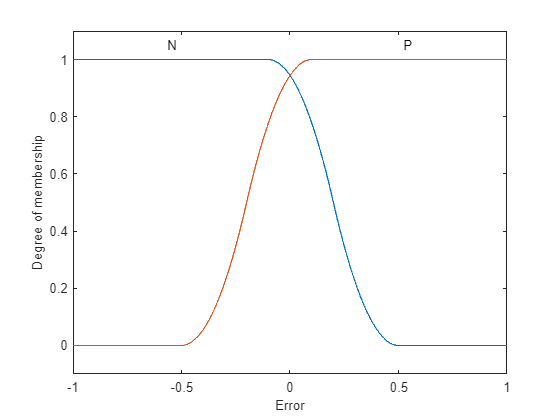

% Create a Fuzzy Inference System (FIS)
bbFIS = mamfis( ...
    'Name', 'Fuzzy Buck-Boost', ...
    'NumInputs', 1, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFS', 2, ...
    'AddRule', 'none');

% Inputs
bbFIS.Inputs(1).Name = 'Error';
bbFIS.Inputs(1).Range = [-1 1];
bbFIS.Inputs(1).MembershipFunctions(1).Name = 'N';
bbFIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';
bbFIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.1 0.5];
bbFIS.Inputs(1).MembershipFunctions(2).Name = 'P';
bbFIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
bbFIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.1];

plotmf(bbFIS, 'input', 1, 1000);

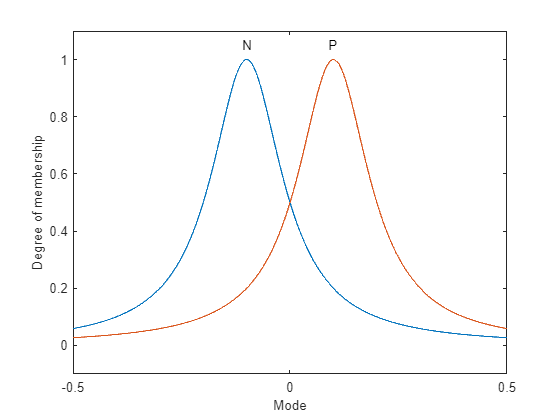


% Outputs
bbFIS.Outputs(1).Name = 'Mode';
bbFIS.Outputs(1).Range = [-0.5 0.5];
bbFIS.Outputs(1).MembershipFunctions(1).Name = 'N';
bbFIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(1).Parameters = [0.1 1 -0.1];
bbFIS.Outputs(1).MembershipFunctions(2).Name = 'P';
bbFIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
bbFIS.Outputs(1).MembershipFunctions(2).Parameters = [0.1 1 0.1];

plotmf(bbFIS, 'output', 1, 1000);

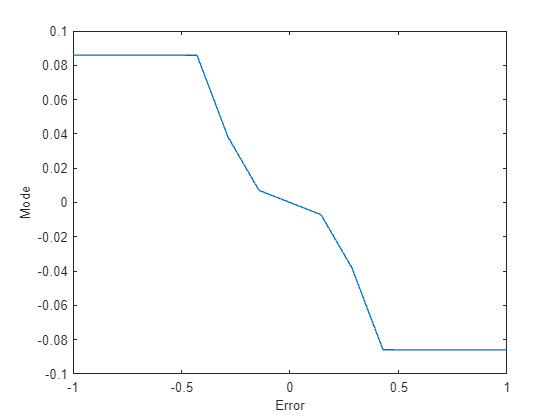

% Specify Rules
rules = [
    "If Error is N then Mode is P";
    "If Error is P then Mode is N";
    ];

bbFIS = addRule(bbFIS, rules);
figure
gensurf(bbFIS)

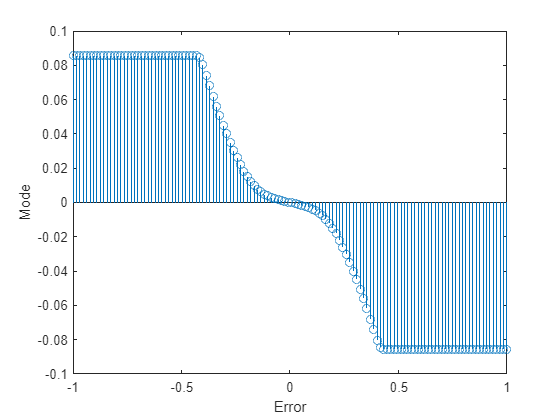

X = linspace(bbFIS.input.range(1), bbFIS.input.range(2), 128)'; % 100 points across input range
Y = evalfis(bbFIS, X); % Evaluate FIS
stem(X, Y);
xlabel('Error');
ylabel('Mode');